# ASTE 583 - Homework 7

## Problem 4

syms x theta U;
f = theta^2*x*exp(-theta*x)*U

$$f = U\,\theta^{2}\,x\,{\mathrm{e}}^{-\theta \,x}$$

f = subs(f,x,1)

$$f = U\,\theta^{2}\,{\mathrm{e}}^{-\theta }$$

U = solve(1 == int(f,theta,[0 inf]), U)

$$U = \frac{1}{2}$$

#### (a) $U = \frac{1}{2}$

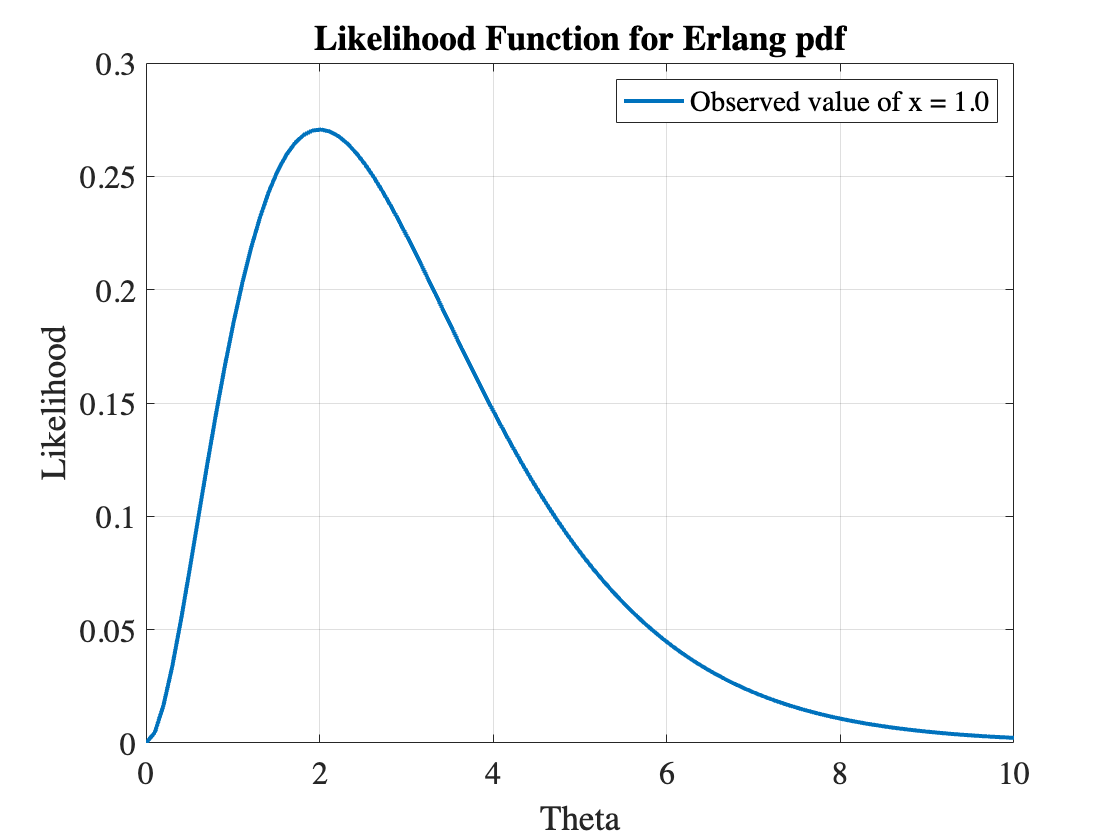

theta = linspace(0, 10);
f = U.*theta.^2.*exp(-theta);
plot(theta, f, 'LineWidth',2)
xlabel('Theta')
ylabel('Likelihood')
title('Likelihood Function for Erlang pdf')
legend('Observed value of x = 1.0')
set(gca,'FontSize',16,'FontName','Calibri')
grid on
box on

#### (b) See graph above

#### (c) The MLE of $\theta$ is 2

## Problem 5

syms mu r C_D A m rho_0 beta h h_0 a_e J_2 phi lambda V_r V_phi V_lambda V_E;
f_g = -mu/r^2*[1;0;0] %Spherical Coordinates

$$f\_g = \left(\begin{array}{c} -\frac{\mu }{r^{2}}\\ 0\\ 0 \end{array}\right)$$

rho = rho_0*exp(-beta*(h-h_0))

$$rho = \rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}$$

V_r = [V_r; V_phi - V_E*cos(phi); V_lambda] %Spherical Coordinates

$$V\_r = \left(\begin{array}{c} V_{r}\\ V_{\varphi }-V_{E}\,\cos\left(\varphi \right)\\ V_{\lambda } \end{array}\right)$$

f_drag = -1/2*rho*C_D*A/m*V_r.^2 %Spherical Coordinates

$$f\_drag = \left(\begin{array}{c} -\frac{A\,C_{D}\,{V_{r}}^{2}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}}{2\,m}\\ -\frac{A\,C_{D}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}\,{\left(V_{\varphi }-V_{E}\,\cos\left(\varphi \right)\right)}^{2}}{2\,m}\\ -\frac{A\,C_{D}\,{V_{\lambda }}^{2}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}}{2\,m} \end{array}\right)$$

U = -mu/r*(a_e/r)^2*J_2*(3*sin(phi)^2 - 1)/2

$$U = -\frac{J_{2}\,{a_{e}}^{2}\,\mu \,\left(3\,{\sin\left(\varphi \right)}^{2}-1\right)}{2\,r^{3}}$$

f_NS = [diff(U,r); 1/r*diff(U,phi); 1/(r*cos(phi))*diff(U,lambda)] %Spherical Coordinates

$$f\_NS = \left(\begin{array}{c} \frac{3\,J_{2}\,{a_{e}}^{2}\,\mu \,\left(3\,{\sin\left(\varphi \right)}^{2}-1\right)}{2\,r^{4}}\\ -\frac{3\,J_{2}\,{a_{e}}^{2}\,\mu \,\cos\left(\varphi \right)\,\sin\left(\varphi \right)}{r^{4}}\\ 0 \end{array}\right)$$

rddot = f_g + f_drag + f_NS %Spherical Coordinates

$$rddot = \left(\begin{array}{c} \frac{3\,J_{2}\,{a_{e}}^{2}\,\mu \,\left(3\,{\sin\left(\varphi \right)}^{2}-1\right)}{2\,r^{4}}-\frac{\mu }{r^{2}}-\frac{A\,C_{D}\,{V_{r}}^{2}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}}{2\,m}\\ -\frac{3\,J_{2}\,{a_{e}}^{2}\,\mu \,\cos\left(\varphi \right)\,\sin\left(\varphi \right)}{r^{4}}-\frac{A\,C_{D}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}\,{\left(V_{\varphi }-V_{E}\,\cos\left(\varphi \right)\right)}^{2}}{2\,m}\\ -\frac{A\,C_{D}\,{V_{\lambda }}^{2}\,\rho_{0}\,{\mathrm{e}}^{-\beta \,\left(h-h_{0}\right)}}{2\,m} \end{array}\right)$$

#### E.O.M. for the term project: $\ddot{r} = \left[ \matrix{
-\frac{\mu}{r^2} - \frac{AC_D\rho_0e^{-\beta (h - h_0)}}{2m}V_r^2 + \frac{3J_2a_e^2\mu}{2r^4}(3\sin^2\phi - 1) \cr
0 - \frac{AC_D\rho_0e^{-\beta (h - h_0)}}{2m}(V_\phi - V_E\cos\phi)^2 - \frac{3J_2a_e^2\mu}{r^4}\cos\phi\sin\phi \cr
0 - \frac{AC_D\rho_0e^{-\beta (h - h_0)}}{2m}V_\lambda^2 + 0
} \right]$